# CSIRS资源映射

CSIRS（Channel-State Information Reference Signal）是一种在5G通信系统中使用的参考信号。它用于获取基站和用户设备之间的信道状态信息（CSI），以便进行信道估计和反馈。

CSIRS在时域上以固定时间间隔发射，并被用户设备接收。通过对接收到的CSIRS信号进行处理，用户设备可以了解到与基站之间的信道质量和特征。这些信息对于实现多种5G技术和功能非常重要，如波束赋形、干扰消除和自适应调制等，有助于提高5G网络的性能、容量和可靠性，从而满足日益增长的无线通信需求。

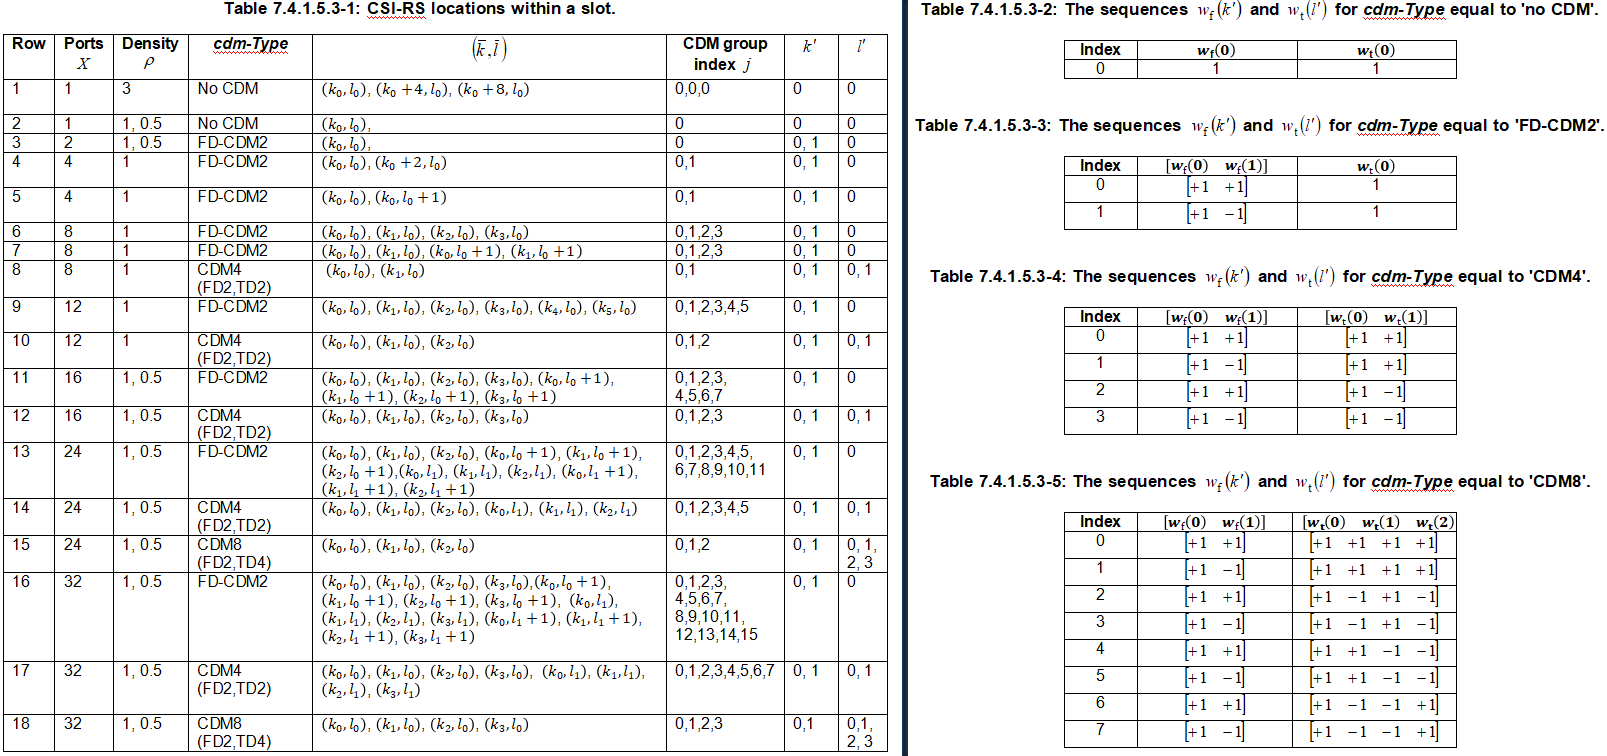

clear;
clc;
close all;

% Carrier configuration
carrier = nrCarrierConfig;
carrier.NCellID = 2;                    % Cell identity
carrier.SubcarrierSpacing = 30;         % Carrier/BWP Subcarrier spacing
carrier.CyclicPrefix = 'normal';        % Cyclic prefix
carrier.NSlot      = 0;                 % Slot counter
carrier.NFrame     = 0;                 % Frame counter
carrier.NStartGrid = 0;                 % Carrier offset
carrier.NSizeGrid  = 273;               % Size of carrier in RB

XXXX

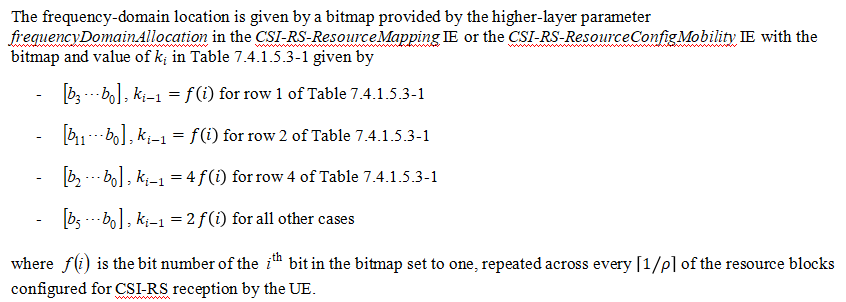

csirs = nrCSIRSConfig;
csirs.CSIRSType = 'NZP';      % 'nzp' | 'zp' 
csirs.CSIRSPeriod = 'on';     % 'on', 'off', [periodicity offset]
csirs.RowNumber = 6;          % [1..18]
csirs.Density = 'one';        % 'one' | 'three' | 'dot5even' | 'dot5odd'
csirs.SymbolLocations = 13;   % [0..13]
csirs.SubcarrierLocations = [0;2;4;6];  % value of k_i [k0;k1;k2;k3], row1 k0 [0..3] | row2 k0 [0..3] | row4 k0 [0..3] | other k0..k5 [0..5]*2
csirs.RBOffset = 0;           
csirs.NumRB = 272; 

disp(['CSIRS资源的port数：' num2str(csirs.NumCSIRSPorts),newline,'CSIRS资源的码分多址类型：' num2str(csirs.CDMType)])

CSIRS资源的port数：8
CSIRS资源的码分多址类型：FD-CDM2


indcsirs = nrCSIRSIndices(carrier,csirs);
symcsirs = nrCSIRS(carrier,csirs);
carrierGrid = nrResourceGrid(carrier,csirs.NumCSIRSPorts);
carrierGrid(indcsirs) = symcsirs;

sym_rb = carrierGrid(1:12,14:14,:);
disp(reshape(sym_rb,[12,csirs.NumCSIRSPorts]));

  列 1 至 6

  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.7071 - 0.7071i  -0.7071 - 0.7071i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 - 0.7071i  -0.7071 + 0.7071i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 

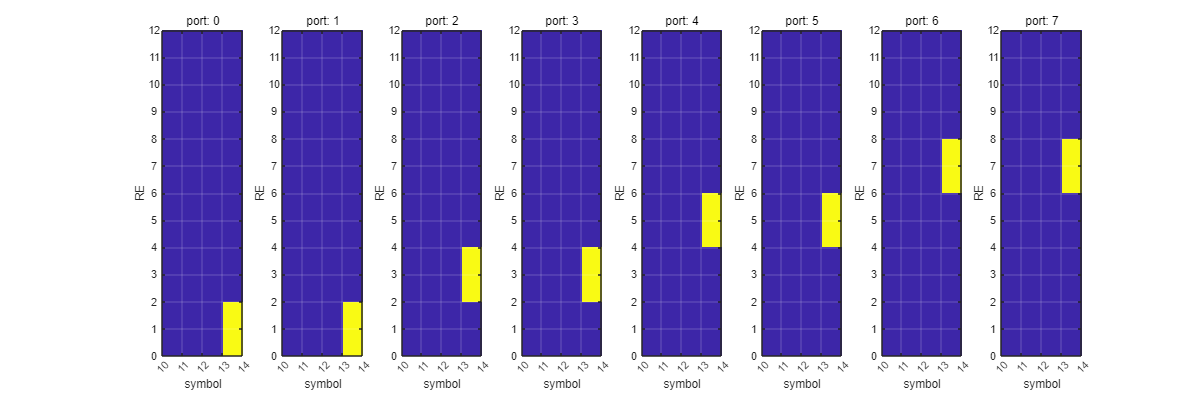


fig = figure;
fig.Position = [100 100 1200 400];
for idx = 1:csirs.NumCSIRSPorts
    subplot(1,csirs.NumCSIRSPorts,idx)
    imagesc(abs(carrierGrid(:,:,idx)));
    set(gca, 'XLim', [10.5, 14.5]);
    set(gca, 'XTick', (10:14)+0.5);
    set(gca, 'XTickLabel', (10:14));
    set(gca, 'XGrid', 'on');
    set(gca, 'GridColor', 'white');
    set(gca, 'YLim', [0.5, 12.5]);
    set(gca, 'YTick', (0:12)+0.5);
    set(gca, 'YTickLabel', (0:12));
    set(gca, 'YGrid', 'on');
    set(gca, 'YDir', 'normal');
    xlabel('symbol');
    ylabel('RE');
    title(['port: ',num2str(idx-1)])
end